load('Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\829_xEMG_CKC_decomp_filtfilt.mat');
addpath 'Z:\code'

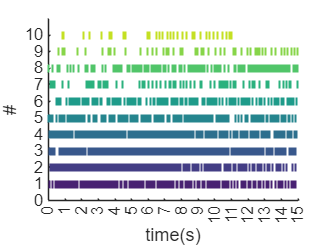

level=1;
trial=6;
% levelref=[2.5,5,7.5,10,2.5];levelnum=levelref(level)

path_fold='Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\';
path_eaf=[path_fold '\eaf\M2L' num2str(level) 'T' num2str(trial) '.eaf'];



eafdata = importdata(path_eaf); % 读取eaf文件
iPulses=eaf2pulse(path_eaf,2048);
Pulses=CKCdecomp{level,trial}.MUPulses;%CKC

draw_PluseTime(iPulses,2048,1,20,1,1);

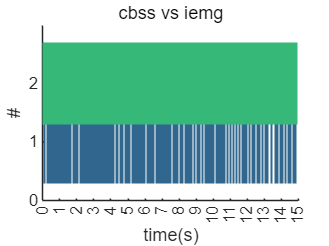

i=51;j=1;
compare{2}=Pulses{i};
compare{1}=iPulses{j};
draw_PluseTime(compare,2048,1,2000,1,1);
title('cbss vs iemg')